clc; clear; close all; tic; % just for loading x, y, u, v
MatLabSettings
load('test.mat');
X = reshape(X,[169,length(X)/169])';
Y = reshape(X,[169,length(Y)/169])';
index = 5;
Ui = U(:,index); Vi = V(:,index);
Ui = reshape(Ui,[169,length(Ui)/169])';
Vi = reshape(Vi,[169,length(Vi)/169])';
Ui(isnan(Ui))=0; Vi(isnan(Vi))=0;

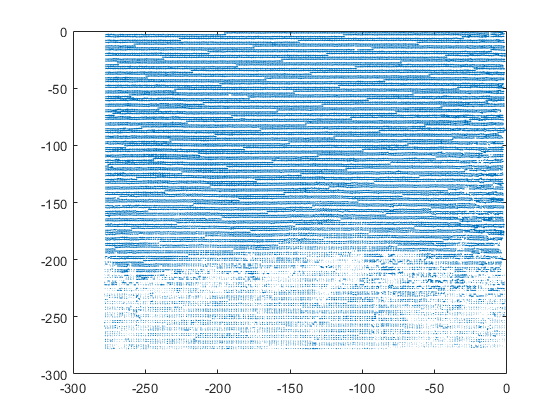

figure()
quiver(X,Y,Ui,Vi,2);

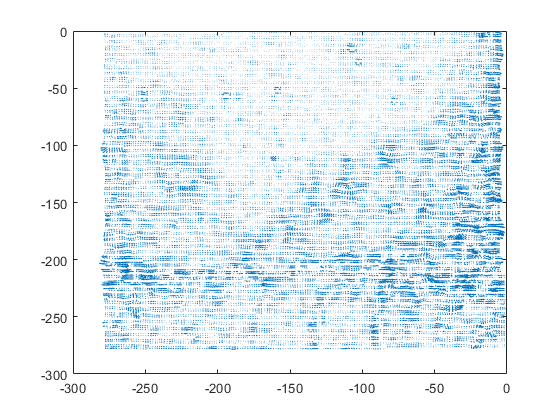

figure() % (size - 1)/4 >= sigma
[U1, V1] = LES(Ui, Vi, 21, 5);  % input is U, V, size, sigma, sigma should be smaller than (size - 1)/4 around
% for jiaming, you can adjust the size, sigma value
quiver(X,Y,U1,V1,2)

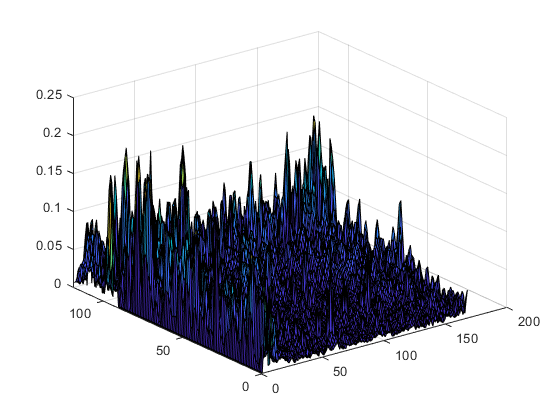

figure()
mag = Speed(U1, V1); % Just for calculate speed for threshold 
surf(mag); % for you to check the speed maginitude distribution

figure()
[U2, V2] = threshold(U1, V1, mag, 0.03, 0.08); % you can just small for threshold to filter out small speed and large value for large speed

[C,h] = contourf(X, Y, U2, 100)

C =    -0.0782  -21.3946  -21.3704  -21.3599  -21.3704  -21.3946   -0.0782  -80.5754  -80.5501  -80.5436  -80.5501  -80.5754   -0.0782 -175.9114 -175.8952 -175.8790 -175.8952 -175.9114   -0.0782  -93.7015  -93.7012  -93.7008  -93.7012  -93.7015   -0.0782 -147.9873 -147.9492 -147.9275 -147.9492 -147.9873   -0.0782 -256.6453 -256.4453 -256.4130 -256.4453 -256.6453   -0.0767 -108.5022 -108.4961 -108.4900 -108.4961 -108.5022   -0.0767  -82.6894  -82.1940  -80.5501  -80.4206  -80.3851  -80.5501  -81.1868
    5.0000 -115.0716 -115.0610 -115.0716 -115.0928 -115.0716    5.0000 -115.0969 -114.6921 -115.0716 -115.0827 -115.0969    5.0000 -195.6217 -195.5861 -195.6217 -195.8545 -195.6217    5.0000 -207.1289 -207.1283 -207.1289 -207.1292 -207.1289    5.0000 -207.1289 -206.7676 -207.1289 -207.2413 -207.1289    5.0000 -221.9238 -221.7265 -221.9238 -222.0606 -221.9238    5.0000  -13.1510  -13.1418  -13.1510  -13.7279  -13.1510    9.0000 -113.4277 -113.1595 -113.2885 -113.4277 -115.0716 -115.3517 -115

h =   Contour with properties:

    LineColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: on
    LevelList: [1×101 double]
        XData: [119×169 double]
        YData: [119×169 double]
        ZData: [119×169 double]

  Show all properties


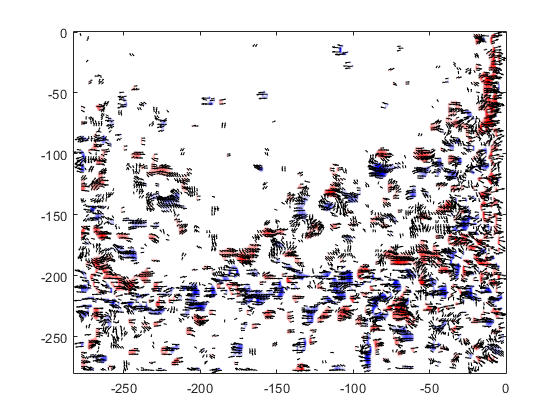

set(h,'LineColor','none')
if isfile('./LiuHongRedBlue.mat')
    load('LiuHongRedBlue.mat');
    colormap(cmap);
else
    colorMap = redblue(100);% if you first time use 
    colormap(colorMap);
end
caxis([-0.07, 0.07])
% colormap summer
hold on;
quiver(X,Y,U2,V2,2,'k')

% You will need to open colormapeditor to edit the color map
% Then you will need to save the color map
% I alread edit it, and save it as redblue. So I can load it with previous
% steps

%1.  colormapedior 

%2. edit

%3 save it
cmap = colormap(gca);
save('LiuHongRedBlue.mat',"cmap");

function [U1, V1] = LES(U,V,si,sigma)
    Vel=U+V*i;
    h = fspecial('gaussian',si,sigma);
    C=filter2(h,ones(size(U)));  % Map edge effects
    Vel=filter2(h,Vel)./C;         % Apply kernel & compensate edges
    Vel=U+V*i-Vel; 
    h2 = fspecial('gaussian', 3, 1);
    Vel=filter2(h2,Vel);
    Vel(:,1)=Vel(:,1)*4/3;              % Compensate edge effects
    Vel(1,:)=Vel(1,:)*4/3;
    Vel(:,end)=Vel(:,end)*4/3;
    Vel(end,:)=Vel(end,:)*4/3;
    U1=real(Vel);                        % Extract new U-component
    V1=imag(Vel);
    U1(find(U == 0)) = 0; V1(find(V == 0)) = 0;
end
function [U1, V1] = threshold(U,V,mag, small, large)
    U1 = U; V1 = V;
    U1(mag < small) = 0;
    V1(mag < small) = 0;
    U1(mag > large) = 0;
    V1(mag > large) = 0;
end
function mag = Speed(U, V)
    mag = sqrt(U.^2 + V.^2);
end
function c = redblue(m)
    if nargin < 1, m = size(get(gcf,'colormap'),1); end
    if (mod(m,2) == 0)
        % From [0 0 1] to [1 1 1], then [1 1 1] to [1 0 0];
        m1 = m*0.5;
        r = (0:m1-1)'/max(m1-1,1);
        g = r;
        r = [r; ones(m1,1)];
        g = [g; flipud(g)];
        b = flipud(r);
    else
        % From [0 0 1] to [1 1 1] to [1 0 0];
        m1 = floor(m*0.5);
        r = (0:m1-1)'/max(m1,1);
        g = r;
        r = [r; ones(m1+1,1)];
        g = [g; 1; flipud(g)];
        b = flipud(r);
    end
    c = [r g b]; 
end